% mikexcohen.com

## prepare details and parameters for time-frequency decomposition

load sampleEEGdata

channel2plot = 'o1';

% wavelet parameters
min_freq =  2;
max_freq = 30;
num_frex = 20;


% baseline time window
baseline_time = [ -400 -100 ];
% convert baseline from ms to indices
baseidx = dsearchn(EEG.times',baseline_time');


% other wavelet parameters
frex = logspace(log10(min_freq),log10(max_freq),num_frex);
time = -1:1/EEG.srate:1;
half_wave = (length(time)-1)/2;

% FFT parameters
nKern = length(time);
nData = EEG.pnts*EEG.trials;
nConv(1:2) = nKern+nData-1;
nConv(3)   = nKern+EEG.pnts-1; % ERP is only one trial-length

% find sensor index
chanidx = find(strcmpi(channel2plot,{EEG.chanlocs.labels}));

% initialize output time-frequency data
tf = zeros(4,length(frex),EEG.pnts);

## prepare non-phase-locked activity

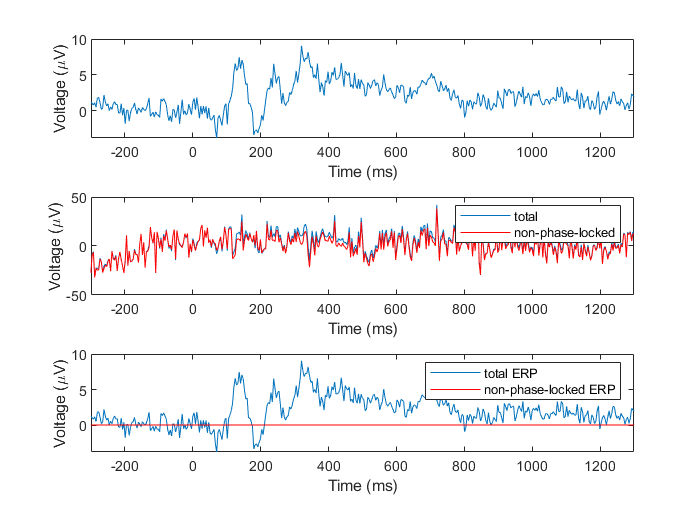

% compute ERP
erp = squeeze(mean(EEG.data(chanidx,:,:),3));

% compute non-phase-locked power by subtracting ERP from each trial
nonphase_EEG = squeeze( bsxfun(@minus,EEG.data(chanidx,:,:),erp) );
% bsxfun in order to substract a vector from matrix


figure(1), clf
subplot(311)
plot(EEG.times,erp)
xlabel('Time (ms)'), ylabel('Voltage (\muV)')
set(gca,'xlim',[-300 1300])

subplot(312)
plot(EEG.times,EEG.data(chanidx,:,10))
hold on
plot(EEG.times,squeeze(nonphase_EEG(:,10)),'r')
legend({'total';'non-phase-locked'})
xlabel('Time (ms)'), ylabel('Voltage (\muV)')
set(gca,'xlim',[-300 1300])

subplot(313)
plot(EEG.times,erp)
hold on
plot(EEG.times,mean(nonphase_EEG,2),'r')
legend({'total ERP';'non-phase-locked ERP'})
xlabel('Time (ms)'), ylabel('Voltage (\muV)')
set(gca,'xlim',[-300 1300])

## time-frequency decomposition

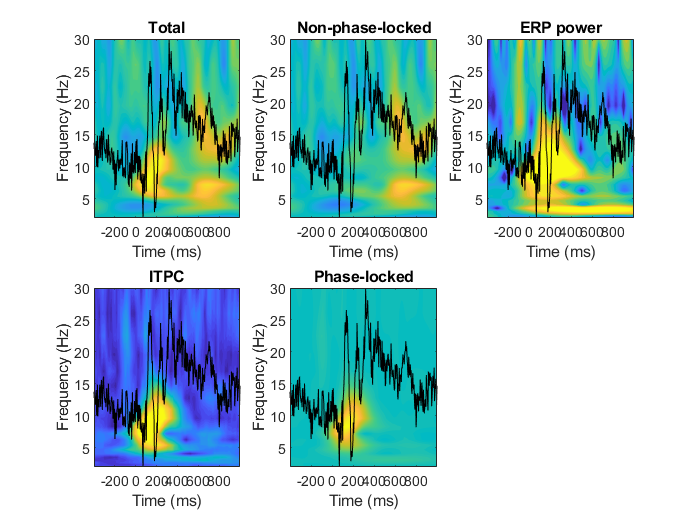

% FFT of total data
fft_EEG{1} = fft( reshape(EEG.data(chanidx,:,:),1,[]), nConv(1));
% FFT of nonphase-locked data
fft_EEG{2} = fft( reshape(nonphase_EEG,1,[]), nConv(2));
% FFT of ERP (phase-locked data)
fft_EEG{3} = fft( erp ,nConv(3));


for fi=1:length(frex)
    
    % create wavelet and get its FFT
    s        = 6/(2*pi*frex(fi));
    wavelet  = exp(2*1i*pi*frex(fi).*time) .* exp(-time.^2./(2*s^2));
    
    % run convolution for each of total, induced, and evoked
    for methodi=1:3
        
        % need separate FFT 
        waveletX = fft(wavelet,nConv(methodi));
        
        % notice that the fft_EEG cell changes on each iteration
        as = ifft(waveletX.*fft_EEG{methodi},nConv(methodi));
        as = as(half_wave+1:end-half_wave);
        if methodi<3
            as = reshape(as,EEG.pnts,EEG.trials);
        
            % compute power
            temppow = mean(abs(as).^2,2);
        else
            temppow = abs(as).^2;
        end
        
        % db correct power
        tf(methodi,fi,:) = 10*log10( temppow ./ mean(temppow(baseidx(1):baseidx(2))) );
        
        % inter-trial phase consistency on total EEG
        if methodi==1
            tf(4,fi,:) = abs(mean(exp(1i*angle(as)),2));
        end
    end % end loop around total, evoked, induced
end % end frequency loop



analysis_labels = {'Total';'Non-phase-locked';'ERP power';'ITPC'};

% color limits
clims = [ -3 3; -3 3; -15 15; 0 .6 ];

% next two lines scale the ERP for plotting on top of the TF plot
erpt = (erp-min(erp))./max(erp-min(erp));
erpt = erpt*(frex(end)-frex(1))+frex(1);

figure(2), clf
for methodi=1:4
    
    subplot(2,3,methodi)
    contourf(EEG.times,frex,squeeze(tf(methodi,:,:)),40,'linecolor','none')
    
    set(gca,'clim',clims(methodi,:),'xlim',[-400 1000],'xtick',-200:200:800)
    xlabel('Time (ms)')
    ylabel('Frequency (Hz)')
    title(analysis_labels{methodi})
    
    % plot ERP on top
    hold on
    plot(EEG.times,erpt,'k')
end

subplot(235)

% estimate phase-locked part of the signal as the difference 
% between the phase-locked and non-phase-locked
phaselockedTF = squeeze(tf(1,:,:) - tf(2,:,:));
% the next line is equivalent to the previous line, just FYI
% phaselockedTF = squeeze(diff(tf([2 1],:,:),[],1));

contourf(EEG.times,frex,phaselockedTF,40,'linecolor','none')
set(gca,'clim',clims(1,:),'xlim',[-400 1000],'xtick',-200:200:800)
xlabel('Time (ms)'), ylabel('Frequency (Hz)')
title('Phase-locked')

% plot ERP on top
hold on
plot(EEG.times,erpt,'k')

## end.